SingleAnalysis = true;



### **Clean Everything Before Start**


% List the variables to keep
keep_vars = {'bi','dirNames','dirPaths','dirPath','dirName','cwd','allDataFolderPath','trialData'};

% Get a list of all variables in the workspace
vars = who;

% Determine which variables to clear
clear_vars = setdiff(vars, keep_vars);

% Clear the unwanted variables
if ~SingleAnalysis
clear(clear_vars{:});
else 
    clear;
end


clc;
format long;

%for Scalogram Analysis
step_window = 10;
window = 30;
excGradTreshhold = 0.03;

### **Select the Specific Log Folder**

The folder Contains 5 files

- PreFlight CAT Test Image

- PreFlight CAT Test CSV

- PostFlight CAT Test Image

- PostFlight CAT Test CSV

- Trial Data .mat File

%select directory
 if ~exist('dirPath','var')
dirPath = uigetdir("logs\firstSeries\","Select the Log Directory...");
else 
   % dirPath = dirTest;
 end
 
listFiles = dir(dirPath);
fileNames = {listFiles.name};
preReportcsv = fullfile(dirPath,fileNames(contains(fileNames,"_pre.csv")));
preReportimg = fullfile(dirPath,fileNames(contains(fileNames,"_pre.jp")));

postReportcsv = fullfile(dirPath,fileNames(contains(fileNames,"_post.csv")));
postReportimg = fullfile(dirPath,fileNames(contains(fileNames,"_post.jp")));

matFile = fullfile(dirPath,fileNames(contains(fileNames,".mat")));

%main mat file

load(string(matFile));


%Print Info for the test details
disp("Test Dir");

Test Dir


disp(dirPath);

C:\Users\Alireza\MATLAB Drive\FatigueThesis\logs\firstSeries\Alireza Ghaderi_08-01-2023_07-35-20



disp("Pilot Info");

Pilot Info


disp(pilot);

           name: 'Alireza Ghaderi'
         rating: 'Student'
       beginPVT: 306
         endPVT: 381
     hoursAwake: 4
     selfRating: 6
      taskTitle: 'OIII ILS 29L/KAZ'
           data: [33674×22 table]
    description: {''}
           time: "08-Jan-2023 07:35:20"
        caffein: 'None'





%load preflight CAT Test

preFlightCAT = catImportFun(string(preReportcsv));
disp("Before Test CAT");

Before Test CAT


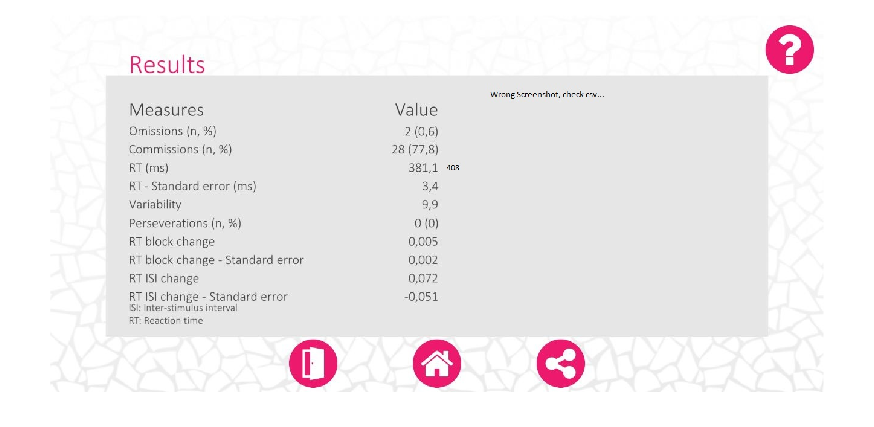

imshow(string(preReportimg));


%load postflight CAT Test

postFlightCAT = catImportFun(string(postReportcsv));
disp("After Test CAT");

After Test CAT


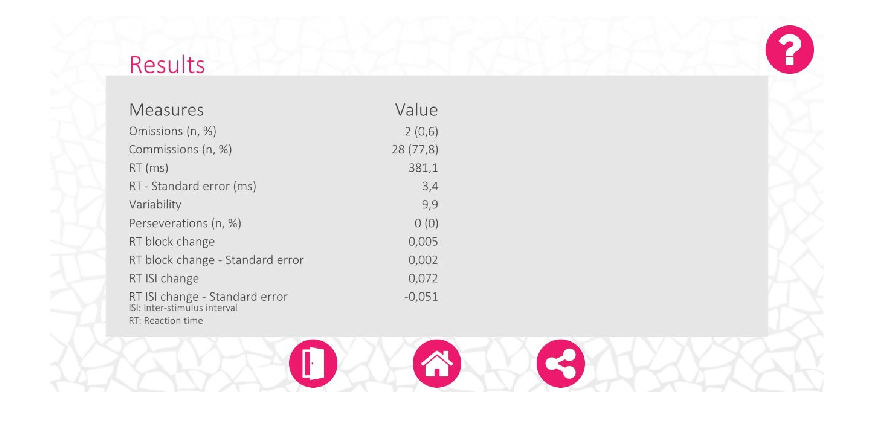

imshow(string(postReportimg));

### **Iris Data Preprocess**

**Remove non-Unique time**

%remove non unique time from data
[C,ia] = unique(pilot.data.time(:,1),'rows');
startPadding = 100;
endPadding = 30;
ia = ia(startPadding:end-endPadding);
data = pilot.data;
data(2:height(data),:) = []

data = 1×22 table
    id          time          irisx    irisy    dxIris    dyIris     aileron       elevator      throttle       rudder        roll       pitch        hdev         vdev       dmeNM        ias       altitude      vvi       heading      rpm       latitude    longitude
    __    ________________    _____    _____    ______    ______    __________    ___________    _________    __________    ________    ________

for col = 1 : width(pilot.data)
    temp = pilot.data(ia,col);
    data(1:height(temp),col) = temp;
end

desireFs = 30;
data = signalResample(data,desireFs);

time = double(data.time);
irisX = data.irisx;
irisY = data.irisy;

%preprocess iris Data
% 
% normIrisX = normalize(irisX);
% normIrisY = normalize(irisY);
iris2d = [normIrisX , normIrisY];

Unrecognized function or variable 'normIrisX'.

normIris = sqrt(irisX.^2 + irisY.^2);
normIris = normalize(normIris);

#### Clean Outlier Data

% Fill outliers
[cleanedData,outlierIndices2,thresholdLow,thresholdHigh] = ...
    filloutliers(normIris,"linear","movmedian",11.2,"ThresholdFactor",2.75,...
    "SamplePoints",time);

% Display results
figure
plot(time,normIris,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,cleanedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

% Plot outliers
plot(time(outlierIndices2),normIris(outlierIndices2),"x",...
    "Color",[64 64 64]/255,"DisplayName","Outliers")

% Plot filled outliers
plot(time(outlierIndices2),cleanedData(outlierIndices2),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([time(:); missing; time(:)],[thresholdHigh(:); missing; thresholdLow(:)],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndices2))
legend
xlabel("time")
clear thresholdLow thresholdHigh




#### Remove Trend

% Remove trend from data
breakpoints = linspace(time(1),time(end),12);
breakpoints([1 end]) = [];
detrendedData = detrend(cleanedData,2,breakpoints,"SamplePoints",time);

% Display results
figure
plot(time,cleanedData,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,detrendedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Detrended data")
plot(time,cleanedData-detrendedData,"Color",[217 83 25]/255,"LineWidth",1,...
    "DisplayName","Trend")
xbreakpoints = repelem(breakpoints,3);
ybreakpoints = repmat([ylim(gca) missing]',numel(breakpoints),1);
plot(xbreakpoints,ybreakpoints,"Color",[51 160 44]/255,"LineWidth",1,...
    "DisplayName","Breakpoints")
hold off
legend
xlabel("time")
clear breakpoints xbreakpoints ybreakpoints

detrendedData = rangeChecker(detrendedData,-1,1);

#### Smooth Data

% Smooth input data
smoothedData = smoothdata(detrendedData,"movmean","SmoothingFactor",0.2,...
    "SamplePoints",time);

% Display results
figure
plot(time,detrendedData,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(time,smoothedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
xlabel("time")


%plot(smoothIris(:,1),smoothIris(:,2))

### Finding Fixation

% Find change points
[changeIndices,segmentMean] = ischange(smoothedData,'linear',"Threshold",0.05,...
    "SamplePoints",time);



% Display results
figure
plot(time,smoothedData,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot segments between change points
plot(time,segmentMean,"Color",[64 64 64]/255,"DisplayName","Segment mean")

hold off
legend
xlabel("time")
clear segmentMean


%fixation analysis
fixationTimes = diff(time(changeIndices));
irisResult.meanFixation = mean(fixationTimes);
irisResult.varFixation = var(fixationTimes);
irisResult.numFixationPerMin = height(fixationTimes)/((max(time)-min(time))/60)

**Scalogram Creation**

### Exceedance Data Analysis

%exceedance
refIas = 90;


 hdev = data.hdev;
 vdev = data.vdev;
 iasDev = (data.ias - refIas); 


hdev = sqrt(hdev.^2);
vdev = sqrt(vdev.^2);
iasDev = sqrt(iasDev.^2); 

% Smooth input data
iasDev = smoothdata(iasDev,"gaussian","SmoothingFactor",0.2,...
    "SamplePoints",time);

% Smooth input data
hdev = smoothdata(hdev,"gaussian","SmoothingFactor",0.2,...
    "SamplePoints",time);

% Smooth input data
vdev = smoothdata(vdev,"gaussian","SmoothingFactor",0.2,...
    "SamplePoints",time);

%Rate Estimator
ts = 1/desireFs;
iasDevDot = diff(iasDev/ts);
hdevDot = diff(hdev)/ts;
vdevDot = diff(vdev/ts);





hdevDot(1:10) = hdevDot(11:20);
vdevDot(1:10) = vdevDot(11:20);
iasDevDot(1:10) = iasDevDot(11:20);
hdevDot(end+1)=0;
vdevDot(end+1)=0;
iasDevDot(end+1)=0;

hdevDot = rangeChecker(hdevDot,-2,2);
vdevDot = rangeChecker(vdevDot,-2,2);
iasDevDot = rangeChecker(iasDevDot,-2,2);

% Fill outliers
[hdevDot,outlierIndices3] = filloutliers(hdevDot,"linear","movmedian",10.067,...
    "ThresholdFactor",0.75,"SamplePoints",time);

% Fill outliers
[vdevDot,outlierIndices4] = filloutliers(vdevDot,"linear","movmedian",3.1,...
    "ThresholdFactor",0.75,"SamplePoints",time);

% Fill outliers
[iasDevDot,outlierIndices4] = filloutliers(iasDevDot,"linear","movmedian",2.1,...
    "ThresholdFactor",0.75,"SamplePoints",time);
% Smooth input data
hdevDot = smoothdata(hdevDot,"movmean","SmoothingFactor",0.2,...
    "SamplePoints",time);
% Smooth input data
vdevDot = smoothdata(vdevDot,"movmean","SmoothingFactor",0.2);
% Smooth input data
iasDevDot = smoothdata(iasDevDot,"movmean","SmoothingFactor",0.2);

%normalize
% default is z-score based on standard deviation
hdev = normalize(hdev,"range",[0 1]);
vdev = normalize(vdev,"range",[0 1]);
iasDev = normalize(iasDev,"range",[0 1]);

hdevDot = normalize(hdevDot);
vdevDot = normalize(vdevDot);
iasDevDot = normalize(iasDevDot);



%exports

figure;
plot(time,hdev);
hold on;
plot(time,vdev);
plot(time,iasDev);
legend(["hdev" "vdev" "iasDev"]);
figure;
hold on;
plot(time,hdevDot);
plot(time,vdevDot);
plot(time,iasDevDot);
legend(["hdevDot" "vdevDot" "iasDevDot"]);


locGain = 1;
locRateGain = 2;
gsGain = 1;
gsRateGain = 2;
iasGain = 0.3 ;
iasRateGain = 0.6 ; 
exceedance = locRateGain* hdevDot + gsRateGain*vdevDot ...
    + iasRateGain* iasDevDot + locGain * hdev ...
    + gsGain* vdev + iasGain* iasDev;
exceedanceResult.exceedanceRaw = exceedance;

% Fill outliers
[exceedance,outlierIndices] = filloutliers(exceedance,"spline",...
    "movmedian",13.1,"ThresholdFactor",2.5,"SamplePoints",time);
exceedance = rangeChecker(exceedance,-5,5);

exceedance = normalize(exceedance);



% Smooth input data
smoothedExceedance = smoothdata(exceedance,"gaussian","SmoothingFactor",0.4,...
    "SamplePoints",time);

% Remove trend from data
breakpoints2 = linspace(time(1),time(end),5);
breakpoints2([1 end]) = [];
detrendedExceedance = detrend(smoothedExceedance,1,breakpoints2,"SamplePoints",time);

% Display results
figure
plot(time,smoothedExceedance,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(time,detrendedExceedance,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Detrended data")
plot(time,smoothedExceedance-detrendedExceedance,"Color",[217 83 25]/255,...
    "LineWidth",1,"DisplayName","Trend")
xbreakpoints2 = repelem(breakpoints2,3);
ybreakpoints2 = repmat([ylim(gca) missing]',numel(breakpoints2),1);
plot(xbreakpoints2,ybreakpoints2,"Color",[51 160 44]/255,"LineWidth",1,...
    "DisplayName","Breakpoints")
hold off
legend
xlabel("time")
clear breakpoints2 xbreakpoints2 ybreakpoints2
detrendedExceedanceNormalized = normalize(detrendedExceedance,"range",[0 1]);
smoothedExceedanceNormalized = normalize(smoothedExceedance,'range',[0 1]);



plot(time,detrendedExceedanceNormalized);
exceedanceResult.meanExceedance = mean(detrendedExceedanceNormalized)
exceedanceResult.varExceedance = var(smoothedExceedanceNormalized)
exceedanceResult.detrendedVarExceedance = var(detrendedExceedanceNormalized)
exceedanceResult.detrendedExceedanceNormalized = detrendedExceedanceNormalized;
exceedanceResult.exceedanceGradient =gradient(detrendedExceedanceNormalized)*1/ts; 

### Average the post and pre CAT results:

% Create an empty struct for the average data
avgCAT = struct();
beforeCAT = preFlightCAT;
afterCAT = postFlightCAT;
% Loop through each struct in the beforeCAT array
for i = 1:length(beforeCAT)
    % Loop through each field in the struct
    fields = fieldnames(beforeCAT(i));
    for j = 1:length(fields)
        % Skip the 'blocks' field
        if strcmp(fields{j},'blocks')
            continue
        end
        % If the field is a scalar or a string, copy it directly to the avgCAT struct
        if isscalar(beforeCAT(i).(fields{j})) || ischar(beforeCAT(i).(fields{j}))
            avgCAT(i).(fields{j}) = (beforeCAT(i).(fields{j}) + afterCAT(i).(fields{j}))/2;
        % If the field is a struct, loop through its fields and average each one
        elseif isstruct(beforeCAT(i).(fields{j}))
            subfields = fieldnames(beforeCAT(i).(fields{j}));
            substruct = struct();
            for k = 1:length(subfields)
                bef = beforeCAT(i).(fields{j}).(subfields{k});
                aft = afterCAT(i).(fields{j}).(subfields{k});
                substruct.(subfields{k}) = (bef+aft)/2 ;
            end
            avgCAT(i).(fields{j}) = substruct;
        % Otherwise, assume the field is an array and average its values element-wise
        else
            avgCAT(i).(fields{j}) = (beforeCAT(i).(fields{j}) + afterCAT(i).(fields{j}))/2;
        end
    end
end

### Output Object Data

%output object definiton
output.trial = pilot;
resampledPilot = pilot;
resampledPilot.data = data;
output.resampledTrial = resampledPilot;
output.preFlightCAT = preFlightCAT;
output.postFlightCAT = postFlightCAT;
output.avgFlightCAT = avgCAT;
output.irisResult = irisResult;
output.exceedanceResult = exceedanceResult;
output.windowInfo.stepTime = step_window;
output.windowInfo.windowTime = window;
output.windowInfo.sampleRate = desireFs;

### Save Scalograms

create_scalogram = true;
remove_existing_scalograms = true;
% step_window = 10;
% window = 30;

if create_scalogram
mkdir(dirPath+"/irisScalogram");
if remove_existing_scalograms
    delete(dirPath+"/irisScalogram/*.jpg");
end


for i=1:step_window:max(time)-window
    start_time = i;
    end_time = i+window-1;

    start_index = find(time==start_time);
    end_index = find(time==end_time);

    buildScalogram(normIris,time,[start_time,end_time]);
%     axis off;
% title("");
% colorbar off;
%     saveas(gcf,dirPath+"\irisScalogram\"+string(start_time)+"_"+string(end_time)+".jpg");

f=getframe; 
imwrite(f.cdata,...
dirPath+"\irisScalogram\"+string(start_time)+"_"+string(end_time)+".jpg");
end
end

### Save Scalograms with Exceedance

create_scalogram_exc = true;
remove_existing_scalograms_exc = true;
% step_window = 10;
% window = 30;

if create_scalogram_exc
mkdir(dirPath+"/irisScalogramWithExc");
if remove_existing_scalograms_exc
    delete(dirPath+"/irisScalogramWithExc/*.jpg");
end


for i=1:step_window:max(time)-window
    start_time = i;
    end_time = i+window-1;
    
    start_index = find(time==start_time);
    end_index = find(time==end_time);

    buildScalogram(normIris,time,[start_time,end_time]);
%     axis off;
%     title("");
%     colorbar off;
meanCurExc = mean(detrendedExceedanceNormalized(start_index : end_index))*10000;
%     saveas(gcf,dirPath+"\irisScalogramWithExc\"+string(int16(meanCurExc))+".jpg")
f=getframe; 
imwrite(f.cdata,dirPath+"\irisScalogramWithExc\"+string(int16(meanCurExc))+".jpg");
end
end


**Binary Alert/None Alert State**

create_scalogram_exc_binary = true;
remove_existing_scalograms_exc_binary = true;
% step_window = 10;
% window = 30;
% excGradTreshhold = 0.03;
if create_scalogram_exc_binary
mkdir(dirPath+"/irisScalogramBinary");
mkdir(dirPath+"/irisScalogramBinary/0");
mkdir(dirPath+"/irisScalogramBinary/1");
if remove_existing_scalograms_exc_binary
    delete(dirPath+"/irisScalogramBinary/0/*.jpg");
    delete(dirPath+"/irisScalogramBinary/1/*.jpg");
end
excGradNormalize = normalize(exceedanceResult.exceedanceGradient,'range',[-1,1]);


for i=1:step_window:max(time)-window
    start_time = i;
    end_time = i+window-1;

    start_index = find(time==start_time);
    end_index = find(time==end_time);
    buildScalogram(normIris,time,[start_time,end_time]);
%     axis off;
%     title("");
%     colorbar off;
excGradNormalize(start_time : end_time);
meanCurExcGradient = mean(excGradNormalize(start_index : end_index));

if(meanCurExcGradient<=excGradTreshhold)
    alertState=1;
    f=getframe; 
    imwrite(f.cdata,dirPath+"\irisScalogramBinary\1\"+string(int16(meanCurExcGradient*1000))+".jpg");
else 
    alertState=0;
    f=getframe; 
imwrite(f.cdata,dirPath+"\irisScalogramBinary\0\"+string(int16(meanCurExcGradient*1000))+".jpg");
end

   
%     saveas(gcf,dirPath+"\irisScalogramWithExc\"+string(int16(meanCurExc))+".jpg")

end
end


